# Network Intrusion Detector

clear;
clc;

## a) load dataset

dataset2 = load("cw_dataset_2class.txt");

% dataset2 = normalize(dataset2)

% shuffle data
selectRows = size(dataset2,1);
shuffle = randperm(selectRows);
shuffledDataset = dataset2(shuffle, :);

% transpose
shuffledDataset = shuffledDataset';
% split testing and training data
[trainingDataset, validationDataset, testingDataset] = dividerand(shuffledDataset, 2/3, 0, 1/3);

## b) Create training data, training target, testing data and testing target. 

%get preprocessing data from columns 1-41 
trainingData = trainingDataset(1:41,:);
% get target data from columns 42
trainingTargetData = trainingDataset(42,:);

% get preprocessing data from columns 1-41 
testingData = testingDataset(1:41,:);
% get target data from columns 42 
testingTarget = testingDataset(42,:);

## c) Select Pattern Recognition Neural Network (patternnet)

% Define the number of neurons
numOfNeurons = 10;
% select pattern net
net = patternnet(numOfNeurons);

## d) Define the number of neurons of the neural network (assume only one hidden layer), define the neural network parameters, e.g. epochs, error goal, and learning rate.

% Define max epoch, error goal and learning rate
epochs = 50;
errorGoal = 0.001;
learningRate = 0.1;

% Update parameters
net.trainParam.epochs = epochs;
net.trainParam.goal = errorGoal;
net.trainParam.lr = learningRate;
% stop testing spit set param to 0 
net.divideParam.testRatio = 0;

e) Train the neural network based on the training dataset created, and view the trained net (similar as Figure 5, input and output numbers are just for illustration).

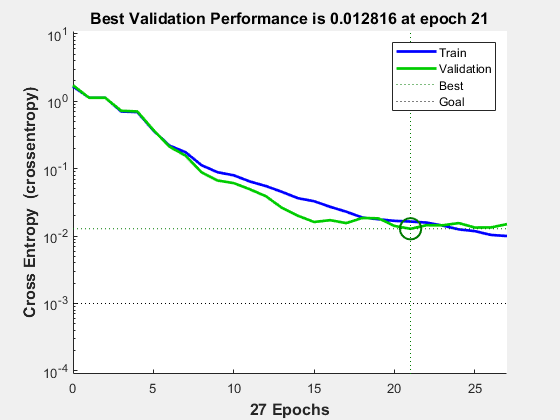

% train dataset 
[net, tr] = train(net, trainingData, trainingTargetData);
view(net)

% plot performance graph
plotperform(tr);

## f) Test the trained net using testing dataset and evaluate its performance (e.g. classifier accuracy and recall rate). You may run several times for training and testing to get an average performance value. 

### Why does each run have different results?

Each run has different results as every time the machine learning algorithm is trained different models are produced due to the algorithm in use not being fully deterministic. Although some features and processes will remain the same most machine learning algorithms have a degree of randomness, making them stochastic. Different models will make different predictions therefore when tested may have different levels of errors and accuracy. An algorithm being stochastic often improves performance for difficult problems and can help avoid getting stuck in local optima.

% array of results
% cross entropy
cEntropys = [];
% Accuracy
accuracies = [];
% Recall Rate
recallRates = [];
% precision
precisions = [];

% run 10 times to gather 10 results for each performance metric 
for it = 1:10
    % Define the number of neurons
    numOfNeurons = 10;

    %select pattern net
    net = patternnet(numOfNeurons);

    % Define epoch, error goal and learning rate
    net.trainParam.epochs = 50;
    net.trainParam.goal = 0.001;
    net.trainParam.lr = 0.1;

    %stop testing spit set param to 0 
    net.divideParam.testRatio = 0;

    % train dataset 
    [net] = train(net, trainingData, trainingTargetData);

    % run neural network on testing data
    predictedData = net(testingData);

    % get performance of the neural network on the testing data
    perp = perform(net, testingTarget, predictedData);
    % display performance value (cross entropy)
%     disp("Cross etropy:" + perp)
    % add cross entropy value to array of cross entropies
    cEntropys(end+1) = perp;
    
    %round predicted array
    predictedRounded = round(predictedData);
    
    % Accuracy
    numCorrectProdictions = 0;
    % loop through both arrays
    for i = 1:size(predictedRounded,2)
        % compare target against predicted
        if(testingTarget(i) == predictedRounded(i))
            % count correct prediction
            numCorrectProdictions = numCorrectProdictions + 1;
        end
    end
    
    %calculate accuracy 
    accuracy = numCorrectProdictions/ size(predictedRounded,2) * 100;
%     disp("Accuracy: " + accuracy + "%")
    % add accuracy value to array of accuracies
    accuracies(end + 1) = accuracy;

    % recall rate
    totalTruePositive = 0;
    totalActualPositive = 0;
    % loop through both arrays
    for i = 1:size(predictedRounded,2)
        % check if true positive
        if(predictedRounded(i) == 1 && predictedRounded(i) == testingTarget(i))
            % count number of true positives
            totalTruePositive = totalTruePositive + 1;
        end
        % check if actual positive
        if(testingTarget(i) == 1)
            % count number of actual positives
            totalActualPositive = totalActualPositive + 1;
        end
    end

    % calculate Recall rate
    recallRate = totalTruePositive / totalActualPositive * 100;
%     disp("Recall Rate: " + recallRate + "%")
    % add Recall rate to array of recall rates
    recallRates(end + 1) = recallRate;
    
    % Precision 
    totalTruePositive = 0;
    totalPredictedPositives = 0;
    for i = 1:size(predictedRounded,2)
        % check if true positive
        if(predictedRounded(i) == 1 && predictedRounded(i) == testingTarget(i))
            % count true positives
            totalTruePositive = totalTruePositive + 1;
        end
        % check if predicted positive
        if(predictedRounded(i) == 1)
            % count predicted positives
            totalPredictedPositives = totalPredictedPositives + 1;
        end
    end

    %calculate Precision
    precision = totalTruePositive/totalPredictedPositives * 100;
%     disp("Precision: " + precision + "%")
    % add precision to array of precisions
    precisions(end + 1) = precision;
end

cEntropys

cEntropys =     0.0237    0.0207    0.0137    0.0189    0.0090    0.0253    0.0121    0.0339    0.0219    0.0222


accuracies

accuracies =    99.0000   99.3333   99.5556   99.4444   99.6667   99.1111   99.5556   99.0000   98.8889   99.3333


recallRates

recallRates =    99.0050   98.7562   99.2537   99.0050   99.5025   98.2587   99.0050   98.5075   98.2587   99.2537


precisions

precisions =    98.7593   99.7487   99.7500   99.7494   99.7506   99.7475  100.0000   99.2481   99.2462   99.2537


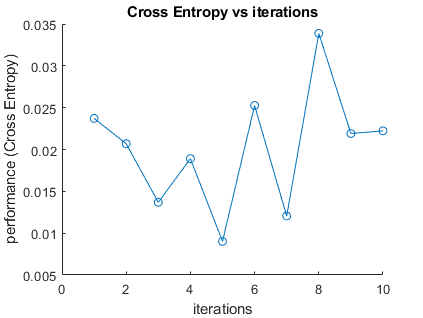


% plot performance metrics 
% cross entropy
figure
hold on
xlabel('iterations')
ylabel('performance (Cross Entropy)')
plot(cEntropys,"o-")
title('Cross Entropy vs iterations')
hold off

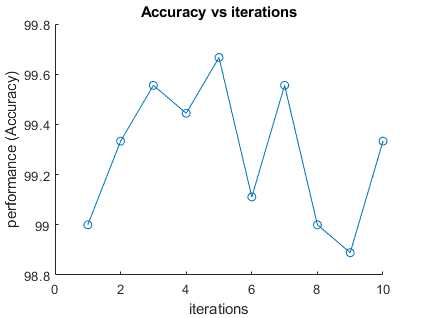

% accuracy
figure
hold on
xlabel('iterations')
ylabel('performance (Accuracy)')
plot(accuracies,"o-")
title('Accuracy vs iterations')
hold off

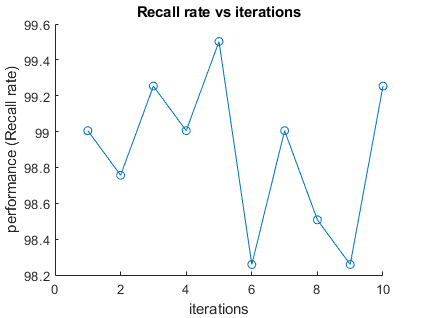

% Recall rate
figure
hold on
xlabel('iterations')
ylabel('performance (Recall rate)')
plot(recallRates,"o-")
title('Recall rate vs iterations')
hold off

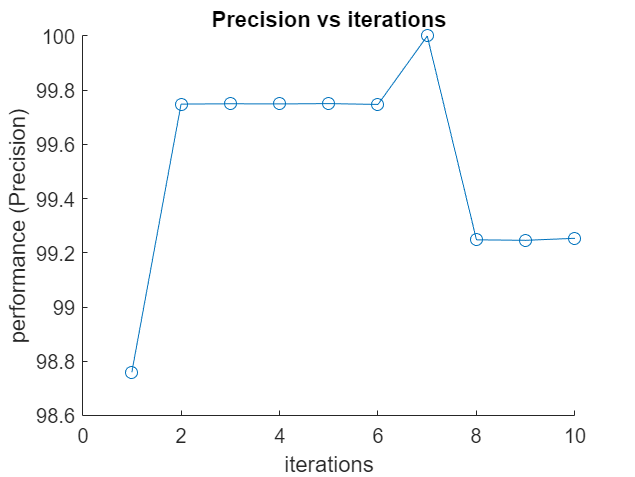

% Precision
figure
hold on
xlabel('iterations')
ylabel('performance (Precision)')
plot(precisions,"o-")
title('Precision vs iterations')
hold off


% average cross entropy
aveCEntropys = sum(cEntropys)/size(cEntropys,2);
disp("Average Cross Entropy: " + aveCEntropys)

Average Cross Entropy: 0.020134


% average Accuracy
aveAccuracy = sum(accuracies)/size(accuracies,2);
disp("Average Accuracy: " + aveAccuracy + "%")

Average Accuracy: 99.2889%


% average Recall rate
aveRecallRate = sum(recallRates)/size(recallRates,2);
disp("Average Recall rate: " + aveRecallRate + "%")

Average Recall rate: 98.8806%


% average Precision
avePrecision = sum(precisions)/size(precisions,2);
disp("Average Precision: " + avePrecision + "%")

Average Precision: 99.5254%



%confusion matrix
[c,cm,ind,per]= confusion(testingTarget, predictedData);
cm

cm =    495     3
     3   399


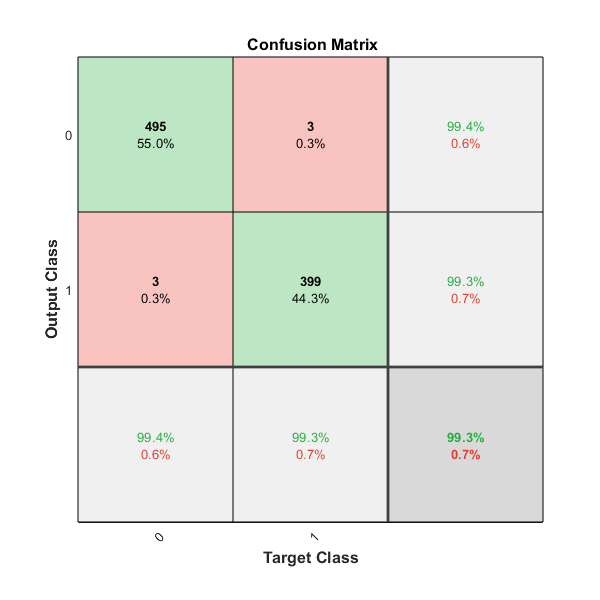

plotconfusion(testingTarget,predictedData)

## g) Explore how neural network parameters (e.g. learning rate) and the number of neurons affect the performance of classifier. 

### Explain what are normal stopping criteria for training.

Changing the number of neurons in a neural network can greatly affect its performance. Having too little neurons could mean the model is unable to find meaningful connections in the data, however having too many neurons may cause an effect called overfitting. Overfitting is when the network becomes too specialised to the training dataset and its performance on unseen data diminishes.

Through testing my algorithm with a range of neurons between 1 and 10 the data shows in most cases the performance appears to improve gradually until the point of 5 neurons. The performance then slightly worsened for the remaining values; however, this was not by much so may be within margin of error.

The learning rate of an algorithm often effects its accuracy, the learning rate is how much the weights change on each iteration. Having a smaller learning rate means smaller adjustments can be made allowing the algorithm to get closer to the error goal. The size of the learning rate usually effects the number of epochs an algorithm needs in order to reach its goal, a smaller learning rate means more epochs.

Through testing my algorithm with a range of learning rates between 1 and 0.0075 the performance appeared to be completely random sometimes the smallest learning rate performed best and others the largest did. This could stem from the randomness of the algorithm, or it could be that the error goal was too large for the learning rate, meaning the algorithm would stop before having the chance to improve past the larger learning rates, although I tried to diminish this by setting the max epoch value to 100 and the error goal to 0.0001.

Stopping criteria

There are three main stopping criteria for neural networks max epochs, error goal and diminished improvement.

Max epochs are set when the network is implemented, it tells the algorithm to stop when a set number of epochs are reached. However, the max epochs are not always reached due to meeting other stopping criteria first.

Error goal is also set during implementation, this is the point in which the implementor feels the algorithm will be effective enough at its intended purpose so the algorithm may top in order to save computations.

The final main stopping criteria is when the performance of the algorithm either stops, diminishes, or begins to get worse. The number of epochs this can happen for can be set prior to implementing the algorithm. 

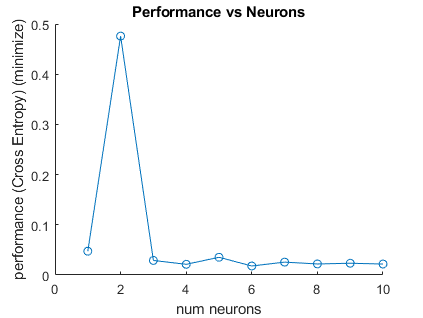

neuronPerformances=[];
for numOfNeurons = 1:10
    %select pattern net
    net = patternnet(numOfNeurons);
    
    % Define epoch, error goal and learning rate
    net.trainParam.epochs = 100;
    net.trainParam.goal = 0.0001;
    net.trainParam.lr = 0.1;
    %stop testing spit set param to 0 
    net.divideParam.testRatio = 0;

    % train network
    [net] = train(net, trainingData, trainingTargetData);
    
    % get performance on test data
    predictedData = net(testingData);
    perf = perform(net, testingTarget, predictedData);

    % add to neuron performance array
    neuronPerformances(end + 1) = perf;
end
% reset number of neurons to 10
numOfNeurons = 10;

%change learning rate 
learningRatePerformance = [];
% learningRates = [1,0.5,0.1,0.05,0.01,0.005,0.001,0.0005,0.0001, 0.00005];
learningRates = [1,0.75,0.5,0.25,0.1,0.075,0.05,0.025,0.01,0.0075];
for it = 1:10
    %select pattern net
    net = patternnet(numOfNeurons);
    
    % Define epochs and error goal
    net.trainParam.epochs = 100;
    net.trainParam.goal = 0.0001;
    %stop testing spit set param to 0 
    net.divideParam.testRatio = 0;

    % Define learning rate
    net.trainParam.lr = learningRates(it);

    %train network
    [net] = train(net, trainingData, trainingTargetData);

    % get performance on test data
    predictedData = net(testingData);
    perf = perform(net, testingTarget, predictedData);

    % add to learning rate performance array
    learningRatePerformance(end + 1) = perf;
end
% learningRatePerformance
% learningRates

% plot perfromance (Cross entropy) graphs
figure
hold on
xlabel('num neurons')
ylabel('performance (Cross Entropy) (minimize)')
plot(neuronPerformances,"o-")
title('Performance vs Neurons')
hold off

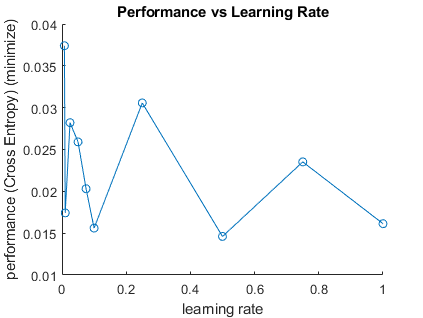


figure
hold on
xlabel('learning rate')
ylabel('performance (Cross Entropy) (minimize)')
plot(learningRates,learningRatePerformance,"o-")
title('Performance vs Learning Rate')
hold off

## h) After completion of intrusion detector for just two classes (‘normal’ and ‘attack’), you now decide to further develop intrusion detection classifier for 3 classes (i.e. ‘normal’, DoS and probing attack), and 5 classes (i.e. ‘normal’, ‘smurf’, ‘neptune, ‘satan’ and ‘ipsweep’). 

### What performance can you get for the intrusion detection classifier?

Running my neural network on 3 and 5 classes has proven the algorithm scaled well as the performance did not reduce at all compared to the performance on the 2 class dataset.

% 3 classes
dataset3 = load("cw_dataset_3class.txt");

% shuffle data
selectRows = size(dataset3,1);
shuffle = randperm(selectRows);
shuffledDataset = dataset3(shuffle, :);
%transpose data
shuffledDataset = shuffledDataset';
[trainingDataset, validationDataset, testingDataset] = dividerand(shuffledDataset, 2/3, 0, 1/3);

trainingData = trainingDataset(1:41,:);
trainingTargetData = trainingDataset(42:44,:);

testingData = testingDataset(1:41,:);
testingTarget = testingDataset(42:44,:);

% Define the number of neurons
numOfNeurons = 10;

%select pattern net
net = patternnet(numOfNeurons);

% Define epoch, error goal and learning rate
epochs = 50;
errorGoal = 0.001;
learningRate = 0.1;

net.trainParam.epochs = epochs;
net.trainParam.goal = errorGoal;
net.trainParam.lr = learningRate;

%stop testing spit set param to 0 
net.divideParam.testRatio = 0;

[net, tr] = train(net, trainingData, trainingTargetData);
view(net)

predictedData = net(testingData);
perp = perform(net, testingTarget, predictedData);
disp("3 class performance: "+ perp);

3 class performance: 0.0076687



[c,cm,ind,per] = confusion(testingTarget, predictedData);
cm

cm =    486     2     0
     1   310     0
     0     0   101



% class 1 True positive, false negative, false positive, true negative
class1TruePositives = cm(1,1);
class1FalseNegatives = sum(cm(1,:)) - class1TruePositives;
class1FalsePositives = sum(cm(:,1)) - class1TruePositives;
class1TrueNegatives = sum(sum(cm(2:3,2:3)));

% class 2 True positive, false negative, false positive, true negative
class2TruePositives = cm(2,2);
class2FalseNegatives = sum(cm(2,:)) - class2TruePositives;
class2FalsePositives = sum(cm(:,2)) - class2TruePositives;
class2TrueNegatives = sum(sum(cm(3:3,3:3))) + sum(cm(1,2:3)) + sum(cm(:,1));

% class 3 True positive, false negative, false positive, true negative
class3TruePositives = cm(3,3);
class3FalseNegatives = sum(cm(3,:)) - class3TruePositives;
class3FalsePositives = sum(cm(:,3)) - class3TruePositives;
class3TrueNegatives = sum(sum(cm(:,:))) - class3FalsePositives - class3FalseNegatives - class3TruePositives;

disp("3 Classification performance metrics")

3 Classification performance metrics


% accuracy
accuracy1 = (class1TruePositives+class1TrueNegatives)/size(predictedData,2)*100;
disp("Class 1 Accuracy: " + accuracy1 + "%")

Class 1 Accuracy: 99.6667%


% precision
precision1 = class1TruePositives/(class1TruePositives+class1FalsePositives)*100;
disp("Class 1 Precision: " + precision1 + "%")

Class 1 Precision: 99.7947%


% recall rate
recallRate1 = class1TruePositives/(class1TruePositives+class1FalseNegatives)*100;
disp("Class 1 Recall Rate: " + recallRate1 + "%")

Class 1 Recall Rate: 99.5902%



% Disp("Class 2")
% accuracy
accuracy2 = (class2TruePositives+class2TrueNegatives)/size(predictedData,2)*100;
disp("Class 2 Accuracy: " + accuracy2 + "%")

Class 2 Accuracy: 100%


% precision
precision2 = class2TruePositives/(class2TruePositives+class2FalsePositives)*100;
disp("Class 2 Precision: " + precision2 + "%")

Class 2 Precision: 99.359%


% recall rate
recallRate2 = class2TruePositives/(class2TruePositives+class2FalseNegatives)*100;
disp("Class 2 Recall Rate: " + recallRate2 + "%")

Class 2 Recall Rate: 99.6785%



% Disp("Class 3")
% accuracy
accuracy3 = (class3TruePositives+class3TrueNegatives)/size(predictedData,2)*100;
disp("Class 3 Accuracy: " + accuracy3 + "%")

Class 3 Accuracy: 100%


% precision
precision3 = class3TruePositives/(class3TruePositives+class3FalsePositives)*100;
disp("Class 3 Precision: " + precision3 + "%")

Class 3 Precision: 100%


% recall rate
recallRate3 = class3TruePositives/(class3TruePositives+class3FalseNegatives)*100;
disp("Class 3 Recall Rate: " + recallRate3 + "%")

Class 3 Recall Rate: 100%



% get the average metrics of 3 classes
disp("Average Accuracy of 3 Classes: " + (accuracy1 + accuracy2 + accuracy3)/3 + "%")

Average Accuracy of 3 Classes: 99.8889%


disp("Average Precision of 3 Classes: " + (precision1 + precision2 + precision3)/3 + "%")

Average Precision of 3 Classes: 99.7179%


disp("Average Recall Rate of 3 Classes: " + (recallRate1 + recallRate2 + recallRate3)/3 + "%")

Average Recall Rate of 3 Classes: 99.7562%


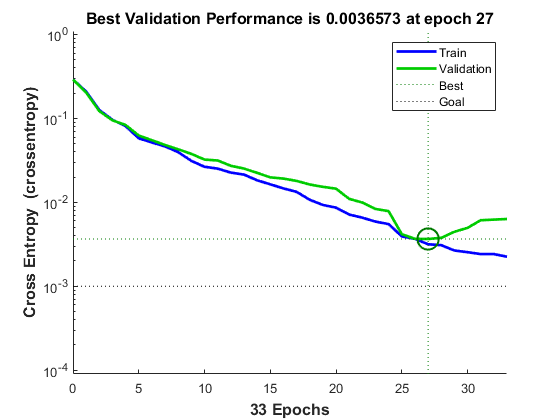


plotperform(tr);%plot performance graph

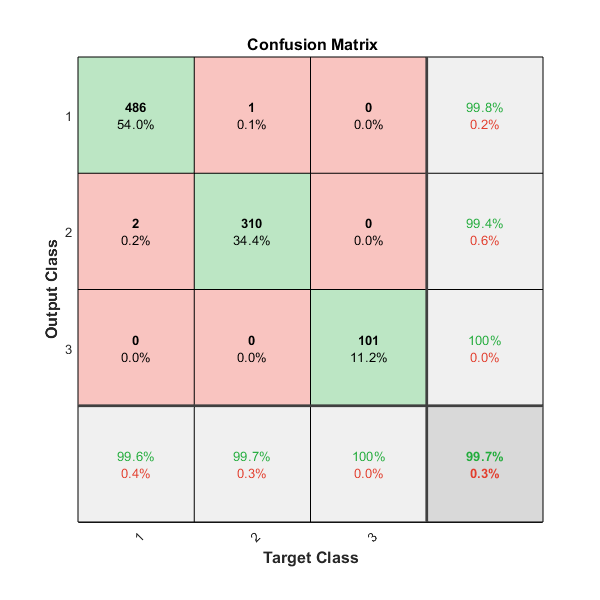

plotconfusion(testingTarget,predictedData)



% 5 classes
dataset5 = load("cw_dataset_5class.txt");

% shuffle data
selectRows = size(dataset5,1);
shuffle = randperm(selectRows);
shuffledDataset = dataset5(shuffle, :);

%transpose data
shuffledDataset = shuffledDataset';

% test train split
[trainingDataset, validationDataset, testingDataset] = dividerand(shuffledDataset, 2/3, 0, 1/3);

trainingData = trainingDataset(1:41,:);
trainingTargetData = trainingDataset(42:46,:);

testingData = testingDataset(1:41,:);
testingTarget = testingDataset(42:46,:);

% Define the number of neurons
numOfNeurons = 10;

% select pattern net
net = patternnet(numOfNeurons);

% Define epoch, error goal and learning rate
epochs = 50;
errorGoal = 0.001;
learningRate = 0.1;

net.trainParam.epochs = epochs;
net.trainParam.goal = errorGoal;
net.trainParam.lr = learningRate;

%stop testing spit set param to 0 
net.divideParam.testRatio = 0;

[net, tr] = train(net, trainingData, trainingTargetData);
view(net)

predictedData = net(testingData);
perp = perform(net, testingTarget, predictedData);
disp("5 class performance: " + perp);

5 class performance: 0.0066214



[c,cm,ind,per] = confusion(testingTarget, predictedData);
cm

cm =    475     1     0     0     0
     0   119     0     0     0
     0     0   103     0     0
     3     0     0   100     0
     2     0     1     0    96



% class 1 True positive, false negative, false positive, true negative
class1TruePositives = cm(1,1);
class1FalseNegatives = sum(cm(1,:)) - class1TruePositives;
class1FalsePositives = sum(cm(:,1)) - class1TruePositives;
class1TrueNegatives = sum(sum(cm(2:5,2:5)));

% class 2 True positive, false negative, false positive, true negative
class2TruePositives = cm(2,2);
class2FalseNegatives = sum(cm(2,:)) - class2TruePositives;
class2FalsePositives = sum(cm(:,2)) - class2TruePositives;
class2TrueNegatives = sum(sum(cm(3:5,3:5))) + sum(cm(1,2:5)) + sum(cm(:,1));

% class 3 True positive, false negative, false positive, true negative
class3TruePositives = cm(3,3);
class3FalseNegatives = sum(cm(3,:)) - class3TruePositives;
class3FalsePositives = sum(cm(:,3)) - class3TruePositives;
class3TrueNegatives = sum(sum(cm(:,:))) - class3FalsePositives - class3FalseNegatives - class3TruePositives;

% class 4 True positive, false negative, false positive, true negative
class4TruePositives = cm(4,4);
class4FalseNegatives = sum(cm(4,:)) - class4TruePositives;
class4FalsePositives = sum(cm(:,4)) - class4TruePositives;
class4TrueNegatives = sum(sum(cm(:,:))) - class4FalsePositives - class4FalseNegatives - class4TruePositives;

% class 5 True positive, false negative, false positive, true negative
class5TruePositives = cm(5,5);
class5FalseNegatives = sum(cm(5,:)) - class5TruePositives;
class5FalsePositives = sum(cm(:,5)) - class5TruePositives;
class5TrueNegatives = sum(sum(cm(:,:))) - class5FalsePositives - class5FalseNegatives - class5TruePositives;

disp("5 Classification performance metrics")

5 Classification performance metrics


% accuracy
accuracy1 = (class1TruePositives+class1TrueNegatives)/size(predictedData,2)*100;
disp("Class 1 Accuracy: " + accuracy1 + "%")

Class 1 Accuracy: 99.3333%


% precision
precision1 = class1TruePositives/(class1TruePositives+class1FalsePositives)*100;
disp("Class 1 Precision: " + precision1 + "%")

Class 1 Precision: 98.9583%


% recall rate
recallRate1 = class1TruePositives/(class1TruePositives+class1FalseNegatives)*100;
disp("Class 1 Recall Rate: " + recallRate1 + "%")

Class 1 Recall Rate: 99.7899%



% Disp("Class 2")
% accuracy
accuracy2 = (class2TruePositives+class2TrueNegatives)/size(predictedData,2)*100;
disp("Class 2 Accuracy: " + accuracy2 + "%")

Class 2 Accuracy: 100%


% precision
precision2 = class2TruePositives/(class2TruePositives+class2FalsePositives)*100;
disp("Class 2 Precision: " + precision2 + "%")

Class 2 Precision: 99.1667%


% recall rate
recallRate2 = class2TruePositives/(class2TruePositives+class2FalseNegatives)*100;
disp("Class 2 Recall Rate: " + recallRate2 + "%")

Class 2 Recall Rate: 100%



% Disp("Class 3")
% accuracy
accuracy3 = (class3TruePositives+class3TrueNegatives)/size(predictedData,2)*100;
disp("Class 3 Accuracy: " + accuracy3 + "%")

Class 3 Accuracy: 99.8889%


% precision
precision3 = class3TruePositives/(class3TruePositives+class3FalsePositives)*100;
disp("Class 3 Precision: " + precision3 + "%")

Class 3 Precision: 99.0385%


% recall rate
recallRate3 = class3TruePositives/(class3TruePositives+class3FalseNegatives)*100;
disp("Class 3 Recall Rate: " + recallRate3 + "%")

Class 3 Recall Rate: 100%



% Disp("Class 4")
% accuracy
accuracy4 = (class4TruePositives+class4TrueNegatives)/size(predictedData,2)*100;
disp("Class 4 Accuracy: " + accuracy4 + "%")

Class 4 Accuracy: 99.6667%


% precision
precision4 = class4TruePositives/(class4TruePositives+class4FalsePositives)*100;
disp("Class 4 Precision: " + precision4 + "%")

Class 4 Precision: 100%


% recall rate
recallRate4 = class4TruePositives/(class4TruePositives+class4FalseNegatives)*100;
disp("Class 4 Recall Rate: " + recallRate4 + "%")

Class 4 Recall Rate: 97.0874%



% Disp("Class 5")
% accuracy
accuracy5 = (class5TruePositives+class5TrueNegatives)/size(predictedData,2)*100;
disp("Class 5 Accuracy: " + accuracy5 + "%")

Class 5 Accuracy: 99.6667%


% precision
precision5 = class5TruePositives/(class5TruePositives+class5FalsePositives)*100;
disp("Class 5 Precision: " + precision5 + "%")

Class 5 Precision: 100%


% recall rate
recallRate5 = class5TruePositives/(class5TruePositives+class5FalseNegatives)*100;
disp("Class 5 Recall Rate: " + recallRate5 + "%")

Class 5 Recall Rate: 96.9697%



% get the average metrics of 5 classes
disp("Average Accuracy of 5 Classes: " + (accuracy1 + accuracy2 + accuracy3 + accuracy4 + accuracy5)/5 + "%")

Average Accuracy of 5 Classes: 99.7111%


disp("Average Precision of 5 Classes: " + (precision1 + precision2 + precision3 + precision4 + precision5)/5 + "%")

Average Precision of 5 Classes: 99.4327%


disp("Average Recall Rate of 5 Classes: " + (recallRate1 + recallRate2 + recallRate3 + recallRate4 + recallRate5)/5 + "%")

Average Recall Rate of 5 Classes: 98.7694%


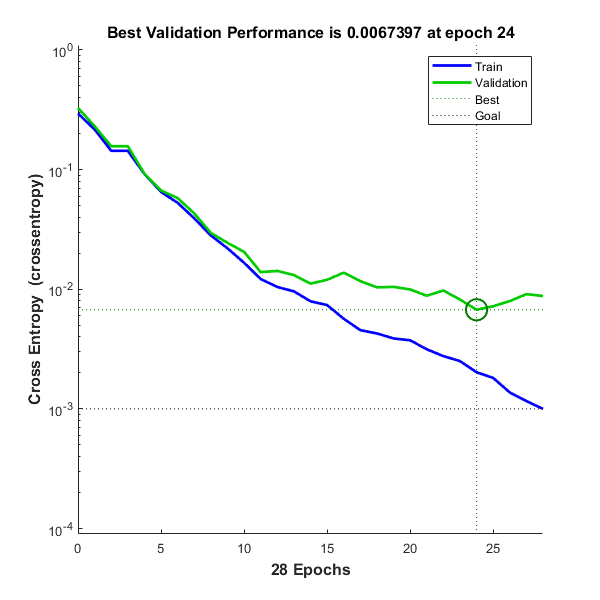


plotperform(tr);%plot performance graph

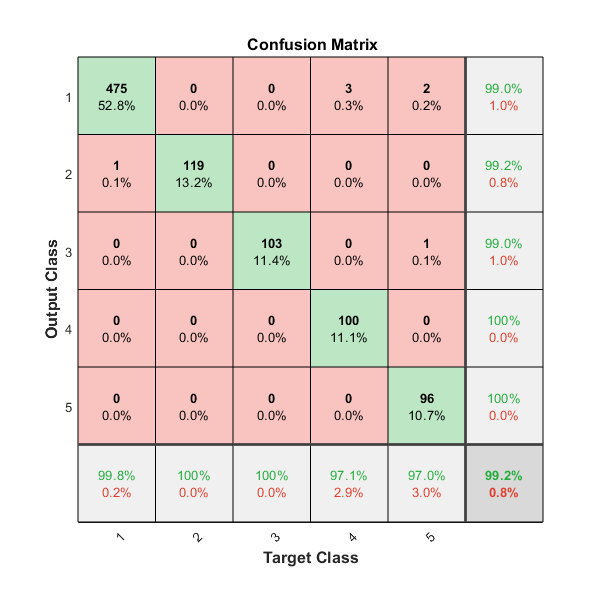


plotconfusion(testingTarget,predictedData)